dengueTable=tabularTextDatastore('dengue.csv');

dengueTable.VariableNames([1 2 3 4 5 6 7 8 9])={'dieaese' 'year' 'month' 'city' 'area' 'gender' 'imported' 'age' 'cases'}

dengueTable =   TabularTextDatastore with properties:

                      Files: {
                             ' ...\h5222\OneDrive\桌面\海海人生\大二下Matlab\2020_MATLAB_FinalProject\dengue.csv'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
      PreserveVariableNames: false
          ReadVariableNames: true
              VariableNames: {'dieaese', 'year', 'month' ... and 6 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ','
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%q', '%f', '%f' ... and 6 more}
                   TextType: 'char'
         ExponentCharacters: 'eEdD'
               CommentStyle: ''
                 Whitespace: ' \b\t'
   

preview(dengueTable)

ans = 8×9 table
     dieaese     year    month      city         area       gender    imported       age       cases
    _________    ____    _____    _________    _________    ______    ________    _________    _____

    {'登革熱'}    2003      1      {'台中市'}    {'大肚區'}    {'M'}      {'是'}     {'55-59'}      1  
    {'登革熱'}    2003      1      {'台中市'}    {'北屯區'}    {'M'}      {'是'}     {'10-14'}      1  
    {'登革熱'}    2003      1      {'台北市'}    {'中山區'}    {'F'}      {'是'}     {'35-39'}      1  
    {'登革熱'}    2003      1      {'台北市'}    {'內湖區'}    {'M'}      {'是'}     {'35-39'}      1  
    {'登革熱'}    2003      1      {'台南市'}    {'安南區'}    {'F'}      {'否'}     {'55-59'}      1  
    {

dengueTall = tall(dengueTable);

yearsCasesCount = sum(gather((dengueTall.year == [2003:2020]) .* dengueTall.cases));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.031 sec
Evaluation completed in 0.041 sec



subplot(2,1,1)
bar([2003:2020], yearsCasesCount, 'FaceColor','#D95319')
set(gca, 'xtick', [2003:1:2020]);
title("年份登革熱病例統計直方圖 (2003 - 2020年)");
xlabel("年份");
ylabel("每年病例數");
%--------------------------------------------------------------------------------%
monthsCasesCount = sum(gather((dengueTall.month == [1:12]) .* dengueTall.cases));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.064 sec
Evaluation completed in 0.099 sec


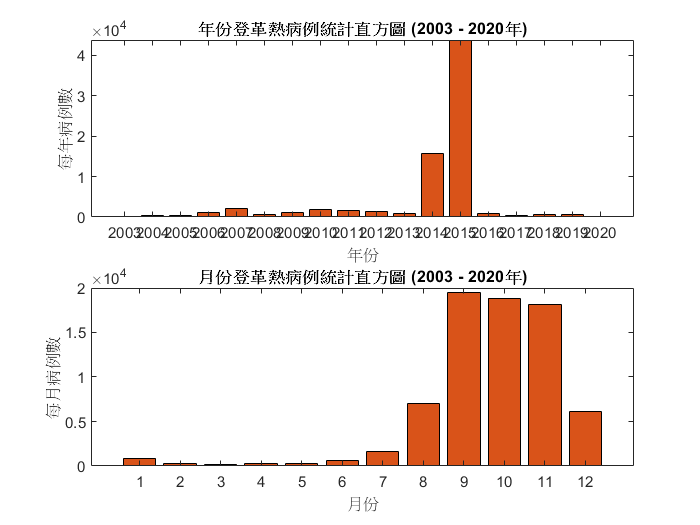


subplot(2,1,2)
bar([1:12], monthsCasesCount, 'FaceColor','#D95319')
set(gca, 'xtick', [1:1:12]);
title("月份登革熱病例統計直方圖 (2003 - 2020年)");
xlabel("月份");
ylabel("每月病例數");

genderTall = gather(dengueTall{:,'gender'});

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.027 sec
Evaluation completed in 0.03 sec


maleCases = gather(dengueTall(find(ismember(genderTall,'M')),:));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.051 sec
- Pass 2 of 2: Completed in 0.058 sec
Evaluation completed in 0.25 sec


femaleCases = gather(dengueTall(find(ismember(genderTall,'F')),:));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.049 sec
- Pass 2 of 2: Completed in 0.059 sec
Evaluation completed in 0.22 sec


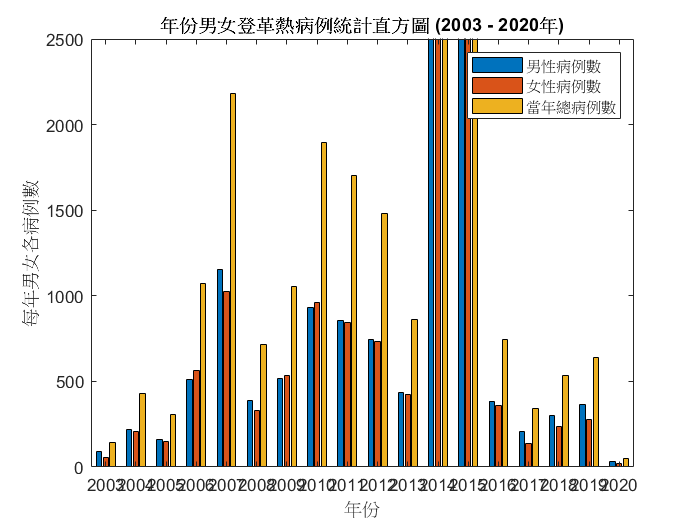

maleCasesCount = sum(gather((maleCases.year == [2003:2020]) .* maleCases.cases));
femaleCasesCount = sum(gather((femaleCases.year == [2003:2020]) .* femaleCases.cases));
totalCasesCount = maleCasesCount + femaleCasesCount;

subplot(1,1,1)
bar([2003:2020],[maleCasesCount; femaleCasesCount; totalCasesCount],'grouped')
set(gca, 'xtick', [2003:1:2020]);
ylim([0 2500]);
title("年份男女登革熱病例統計直方圖 (2003 - 2020年)");
xlabel("年份");
ylabel("每年男女各病例數");
legend('男性病例數','女性病例數', '當年總病例數');

importedTall = gather(dengueTall{:,'imported'});

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.026 sec
Evaluation completed in 0.027 sec


localCases = gather(dengueTall(find(ismember(importedTall,'否')),:));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.048 sec
- Pass 2 of 2: Completed in 0.059 sec
Evaluation completed in 0.22 sec


abroadCases = gather(dengueTall(find(ismember(importedTall,'是')),:));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.045 sec
- Pass 2 of 2: Completed in 0.067 sec
Evaluation completed in 0.23 sec


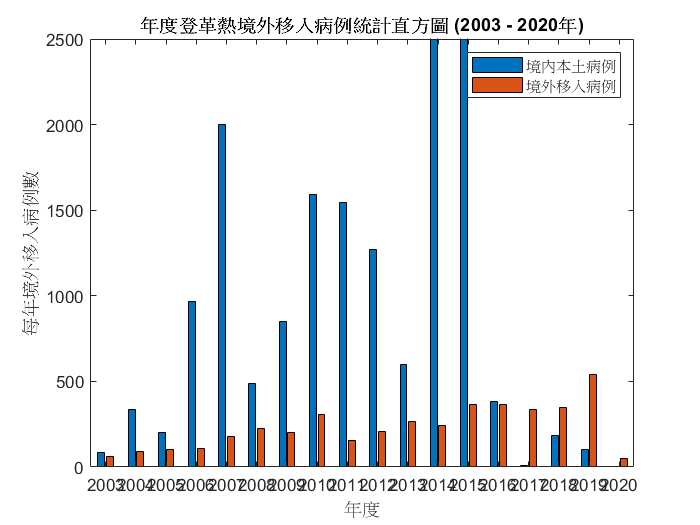

localCasesCount = sum(gather((localCases.year == [2003:2020]) .* localCases.cases));
abroadCasesCount = sum(gather((abroadCases.year == [2003:2020]) .* abroadCases.cases));

subplot(1,1,1)
bar([2003:2020],[localCasesCount; abroadCasesCount],'grouped')
set(gca, 'xtick', [2003:1:2020]);
ylim([0 2500]);
title("年度登革熱境外移入病例統計直方圖 (2003 - 2020年)");
xlabel("年度");
ylabel("每年境外移入病例數");
legend('境內本土病例','境外移入病例');